# Sync the data between IMU and MC system

## Purpose of file

- Sync the time between the IMU measurements and the MC measurements, that is, estimate the time-shift. 

- FInd the coarse and fine rotation between the twos.

- The time shift is estimated by estimating the angular velocities from the rotation matrices from the MC systems and compare with the angular velocities by the gyroscopes. If they are not aligned, one should compare the norm of the angular velocities, but the coarse alignment was sufficient to get the rotation around the x-axis. The the x component is only compared. Then time shift IMU x-component of omega and sum the squared differences. 

- A fine alignment is also performed by comparing the direction of gravity. This is not so important since this misalignment will be incorporated into the $R$ matrix in the filter. We will not compare rotation matrices only positions.

## Load Data


% Estimate bias from stationary phase.
% FIG_SIZE = [0,0,800*1.5,500*1.5]

normalize_norm_v = @(x) x ./ norm_time(x);


### Load MC data

serie = 2;
exp = 4;

% Load MC data 
% Load MC data 
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/experiments/liu/serie-2/exp4'



file_mc  =sprintf("imu-%d-000%d.mat", serie, exp);
load(fullfile(pathScript,"raw_data","mc",file_mc));

% Load the data 
newStr = sprintf("imu_%d_000%d", serie, exp);
data_mc = eval(newStr);

### Load IMU data

data_IMU = load(fullfile(pathScript,"raw_data","imu","data_same_frame.mat"));

## Prepare data

N_sens = size(data_IMU.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2);
inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);
data_IMU.gyro = deg2rad(data_IMU.inertial_data_double_rot(inds_gyro,:));
data_IMU.acc = data_IMU.inertial_data_double_rot(inds_acc,:);
data_IMU.time = data_IMU.time_stamp_corr - data_IMU.time_stamp_corr(1);
data_IMU.acc

ans =    -0.6273   -0.6081   -0.6416   -0.5986   -0.6560   -0.6321   -0.6704   -0.6129   -0.6321   -0.7087   -0.6177   -0.6081   -0.6129   -0.6991   -0.7039   -0.5459   -0.6704   -0.6560   -0.6560   -0.7230   -0.6321   -0.5794   -0.6321   -0.6656   -0.6752   -0.6800   -0.6369   -0.6033   -0.6800   -0.6512   -0.6081   -0.6512   -0.5938   -0.6560   -0.6608   -0.6656   -0.6512   -0.7326   -0.6225   -0.6560   -0.6416   -0.6273   -0.6033   -0.6225   -0.5842   -0.6225   -0.6369   -0.6704   -0.6273   -0.6560
   -0.1389   -0.1963   -0.2011   -0.2682   -0.1580   -0.1963   -0.1724   -0.2011   -0.1437   -0.1676   -0.1676   -0.1484   -0.1867   -0.2059   -0.2155   -0.2203   -0.2155   -0.2203   -0.1532   -0.1915   -0.2107   -0.1772   -0.1963   -0.1820   -0.2059   -0.2011   -0.2538   -0.2107   -0.1963   -0.1532   -0.1437   -0.2251   -0.1389   -0.2203   -0.1963   -0.2059   -0.2059   -0.2251   -0.1532   -0.1820   -0.1820   -0.1580   -0.2059   -0.1963   -0.2155   -0.1963   -0.2059   -0.2203   -0.1628   

R_imu2rig_coarse = [ 
    0   -1  0;
    -1  0  0;
    0  0 -1];

data_IMU_mc_frame = struct;
R_imu2rig_coarse

R_imu2rig_coarse =      0    -1     0
    -1     0     0
     0     0    -1


% First around z, then around y, then around x
eul2rotm(deg2rad([-90 0 180]))

ans =     0.0000   -1.0000   -0.0000
   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000


R_imu2rig_coarse - eul2rotm(deg2rad([-90 0 180]))

ans = 	1.0e+-15 *

   -0.0612         0    0.1225
         0    0.0612    0.0000
         0   -0.1225         0


data_IMU_mc_frame.r0 = R_imu2rig_coarse*data_IMU.r0

data_IMU_mc_frame = struct with fields:
    r0: [3×32 double]


data_IMU.r0*1e3

ans =    -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500
    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


data_IMU_mc_frame.r0*1e3

ans =    -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500
    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500
   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000


R_imu2rig_coarse_tot = kron(eye(N_imu), R_imu2rig_coarse);
data_IMU_mc_frame.acc = R_imu2rig_coarse_tot*data_IMU.acc;
data_IMU_mc_frame.gyro = R_imu2rig_coarse_tot*data_IMU.gyro;
data_IMU_mc_frame.time = data_IMU.time;
data_IMU_mc_frame.Ts = data_IMU.Ts;
data_IMU_mc_frame.Fs = data_IMU.Fs;
data_IMU_mc_frame.mean_gyro = triad_mean(data_IMU_mc_frame.gyro);
data_IMU_mc_frame.mean_acc = triad_mean(data_IMU_mc_frame.acc);
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

#### Check MC Data

There are some missing samples in the MC data

p_mm = squeeze(data_mc.RigidBodies.Positions); % Positions in mm

bad_points = logical(any(isnan(p_mm)));
good_points = ~bad_points;

p_tot = p_mm/1000;
p = p_tot(:,good_points);
t_tot = ((data_mc.StartFrame:data_mc.Frames) - 1)/data_mc.FrameRate;
t = t_tot(good_points);


## Check Time 

#### Missing samples in the MC system

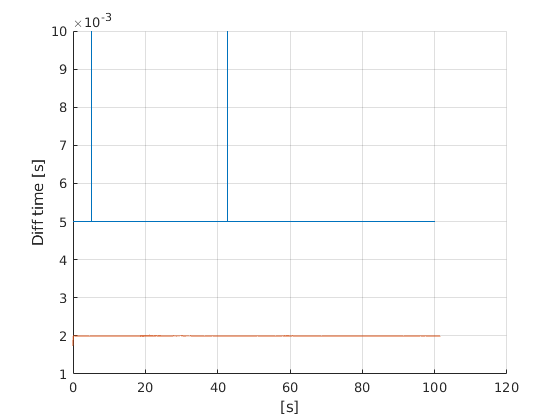

figure(); hold on
plot(t(1:end-1), diff(t), 'DisplayName',"Motion Capture")
plot(data_IMU.time(1:end-1),diff(data_IMU.time),'DisplayName',"IMU")
xlabel("[s]")
ylabel("Diff time [s]")
grid on

Some missing samples.

#### 3D plot of trajectory MC system

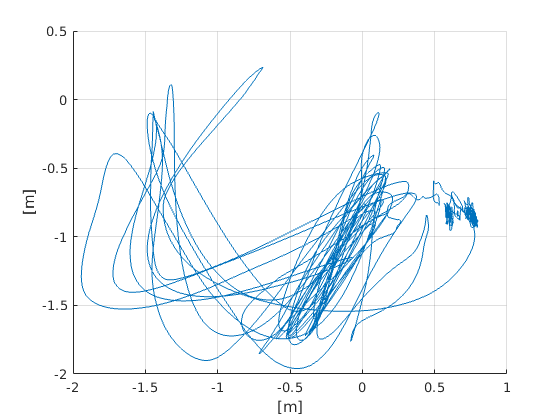

figure(); clf; hold on
plot3(p(1,:),p(2,:), p(3,:))

grid on

xlabel("[m]")
ylabel("[m]")

### Check position in regular 2D plot

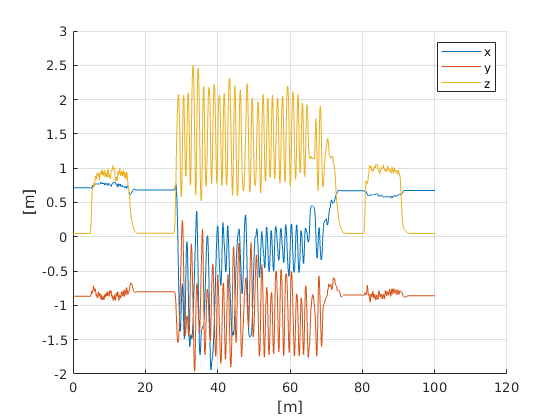

dirs = ["x","y","z"];
figure(); clf; hold on
for i =1:3
    plot(t, p(i,:),"DisplayName",dirs(i))
end

grid on
legend()
xlabel("[m]")
ylabel("[m]")

#### Rig rotation matrix

The rotation matrix is from local to global, that is body to global 

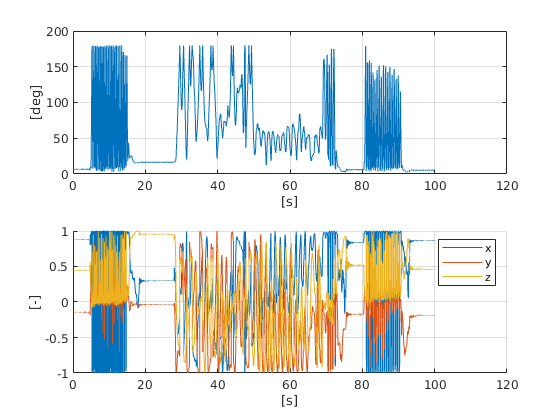

R_nb_rig_tot = squeeze(data_mc.RigidBodies.Rotations); % Rotation matrix
R_nb_rig = R_nb_rig_tot(:,good_points); % Take away nans 
R_nb_rig_3x3 = reshape(R_nb_rig,3,3,[]);
R_bn_rig_3x3 = zeros(size(R_nb_rig_3x3));

for n = 1:size(R_nb_rig_3x3,3)
    R_bn_rig_3x3(:,:,n) = R_nb_rig_3x3(:,:,n)';
end

figure(); hold on
ax = zeros(2,1);

axang = rotm2axang(R_nb_rig_3x3);
ax(1) = subplot(2,1,1);


plot(t, rad2deg(axang(:,4)))
% set(gca, "YScale", "log")
grid on
xlabel("[s]")
ylabel("[deg]")


ax(2) = subplot(2,1,2); hold on
for i = 1:3
    plot(t, axang(:,i))
end
grid on
legend("x","y","z")
xlabel("[s]")
ylabel("[-]")


% linkaxes(ax, "x");

## Estimate angular velocity from MC rotation matrices 

Use a forward differencing scheme.

w_nb_hat =  R2w_central_diff(R_nb_rig_3x3, t)

w_nb_hat =        NaN    0.0175   -0.0377   -0.0397    0.0761   -0.0262   -0.0247   -0.0330   -0.0556   -0.0162    0.0096    0.0800    0.0675   -0.1307   -0.0509    0.0855    0.0098    0.0402   -0.0513   -0.0348    0.0242    0.0213    0.0027   -0.0062    0.0058    0.0011    0.0075   -0.0096    0.0295   -0.0167   -0.0366   -0.0147   -0.0163    0.0409    0.0131   -0.0137    0.0154   -0.0017    0.0203   -0.0713   -0.0827    0.1047    0.0514   -0.0520    0.0092   -0.0387   -0.0012    0.0511   -0.0319   -0.0188
       NaN   -0.0084   -0.0167   -0.0149    0.0138    0.0199    0.0047    0.0047    0.0003   -0.0083   -0.0094    0.0167    0.0257   -0.0108   -0.0159    0.0056    0.0023    0.0192    0.0147   -0.0189   -0.0074   -0.0050    0.0028    0.0259   -0.0034   -0.0299   -0.0076    0.0129    0.0031   -0.0156    0.0084    0.0077    0.0083    0.0112   -0.0101    0.0005   -0.0094   -0.0024   -0.0007    0.0042    0.0085   -0.0030   -0.0060   -0.0007   -0.0020    0.0007    0.0056   -0.0052   -0.00

% Set the neighbours
w_nb_hat(:,1) = w_nb_hat(:,2);
w_nb_hat(:,end) = w_nb_hat(:,end-1);
% zeros(3,length(t));
% 
% for k = 2:length(t)
%     dt = t(k) - t(k-1);
%     w_nb_hat(:,k) = logSO3(R_nb_rig_3x3(:,:,k-1)'*R_nb_rig_3x3(:,:,k))/dt;
% end


## Rotate IMU to IMU-rig coarse

Found this matrix by looking at the photos.

### Plot angular velocity components

figure()
ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU_mc_frame.time, data_IMU_mc_frame.mean_gyro(i,:), "DisplayName","IMU")
    grid on 
    legend
end
linkaxes(ax, 'x'); clf reset;

Looks like they are the same.

### Plot angular velocity norm

Compare the norm instead, not depedent on the orientation of the rig

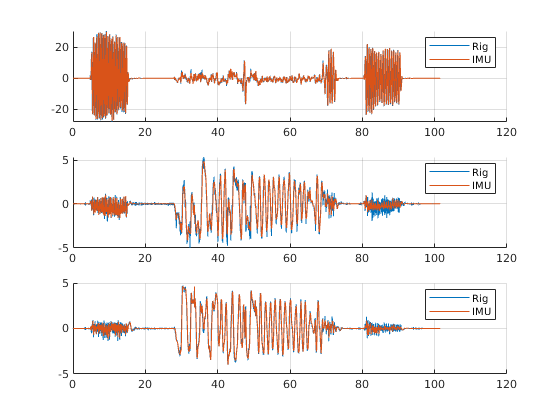

figure()

ax = zeros(3,1);
hold on
plot(t, norm_time(w_nb_hat), "DisplayName","Rig")
plot(data_IMU.time, norm_time(data_IMU_mc_frame.mean_gyro), "DisplayName","IMU")
grid on 
legend

The normed signal of the angular velocity does not look very smooth, that can be explained by the $y$ and $z$ components that are quire noisy. It is then better to just use $x$ component.

## Estimate rotation matrix between IMU and rig using gravity (Fine alignment)

The body frames of the IMU and the rig is not perfectly aligned. 

Downward in bodyframe should point in the direction of gravity in body frame coordinates.

Downward of the navigation frame is the third column of the R_bn matrix, the rotation matrix from navigation frame to body frame.

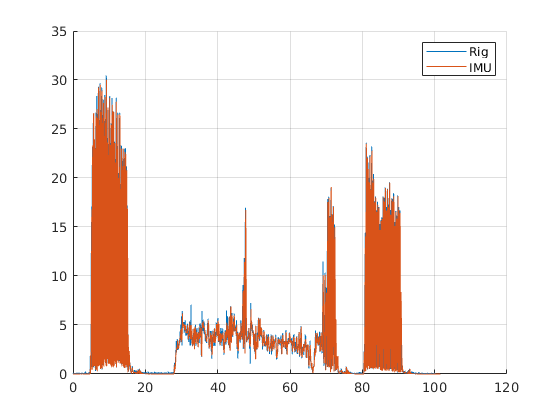

rig_unit_tot = reshape(R_bn_rig_3x3(:,3,:),3,[])
imu_unit_tot = normalize_norm_v(data_IMU_mc_frame.mean_acc)

mask_stationary_rig = t <= 0.5;
mask_stationary_IMU = data_IMU_mc_frame.time <= 4;

figure(); 

rig_unit_tot =     0.0200    0.0200    0.0200    0.0202    0.0202    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0201    0.0199    0.0198    0.0200    0.0200    0.0199    0.0199    0.0197    0.0198    0.0199    0.0199    0.0199    0.0199    0.0197    0.0199    0.0200    0.0200    0.0199    0.0199    0.0200    0.0199    0.0199    0.0198    0.0198    0.0199    0.0198    0.0200    0.0198    0.0200    0.0198    0.0199    0.0198    0.0199    0.0199    0.0200    0.0198    0.0199    0.0199    0.0200
    0.1044    0.1040    0.1046    0.1036    0.1042    0.1044    0.1039    0.1041    0.1036    0.1036    0.1034    0.1037    0.1042    0.1044    0.1029    0.1038    0.1038    0.1039    0.1042    0.1034    0.1039    0.1037    0.1041    0.1037    0.1040    0.1038    0.1040    0.1038    0.1039    0.1041    0.1038    0.1038    0.1036    0.1036    0.1040    0.1037    0.1039    0.1039    0.1039    0.1041    0.1031    0.1033    0.1042    0.1038    0.1037    0.1039    0.1033    0.1039    

for i = 1:3

imu_unit_tot =     0.0036    0.0050    0.0036    0.0043    0.0044    0.0038    0.0054    0.0034    0.0040    0.0039    0.0033    0.0041    0.0042    0.0027    0.0051    0.0041    0.0038    0.0044    0.0032    0.0045    0.0055    0.0035    0.0042    0.0047    0.0033    0.0040    0.0034    0.0050    0.0033    0.0038    0.0045    0.0043    0.0044    0.0047    0.0031    0.0054    0.0046    0.0041    0.0027    0.0036    0.0032    0.0036    0.0031    0.0036    0.0029    0.0038    0.0043    0.0040    0.0040    0.0043
    0.0598    0.0608    0.0603    0.0603    0.0613    0.0606    0.0614    0.0612    0.0613    0.0605    0.0621    0.0600    0.0608    0.0608    0.0617    0.0613    0.0612    0.0612    0.0610    0.0604    0.0611    0.0601    0.0613    0.0606    0.0616    0.0618    0.0605    0.0610    0.0610    0.0615    0.0616    0.0620    0.0604    0.0622    0.0618    0.0606    0.0613    0.0613    0.0626    0.0611    0.0614    0.0608    0.0607    0.0621    0.0621    0.0606    0.0615    0.0616    

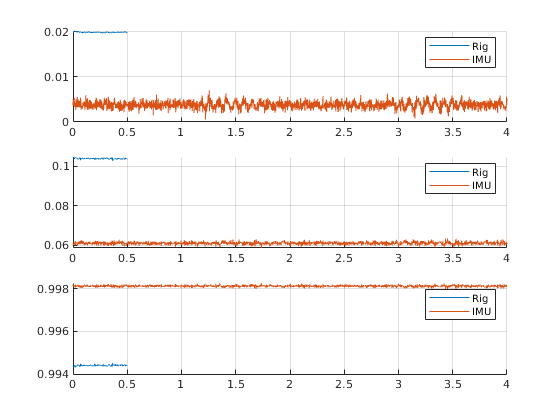

    subplot(3,1,i); hold on 
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot(i,mask_stationary_IMU), "DisplayName","IMU")
    grid on 
    legend
end

### Find angle difference 

[R_stationary_rig_mean, e_R] = average_rotation(R_bn_rig_3x3(:,:,mask_stationary_rig), 100, 1e-12)

1/100: tol: 6.469e-04 / 1.000e-12
2/100: tol: 9.211e-12 / 1.000e-12
3/100: tol: 5.838e-18 / 1.000e-12


R_stationary_rig_mean =     0.9985    0.0516    0.0199
   -0.0534    0.9932    0.1038
   -0.0144   -0.1047    0.9944


e_R =    -0.0006   -0.0002   -0.0008    0.0001   -0.0004   -0.0006   -0.0002   -0.0004    0.0002    0.0002    0.0003    0.0001   -0.0005   -0.0006    0.0008   -0.0001   -0.0000   -0.0002   -0.0004    0.0004   -0.0001    0.0001   -0.0003    0.0001   -0.0002    0.0000   -0.0002   -0.0000   -0.0001   -0.0003    0.0000    0.0000    0.0002    0.0002   -0.0002    0.0001   -0.0001   -0.0001   -0.0001   -0.0003    0.0006    0.0005   -0.0004    0.0000    0.0001   -0.0001    0.0005   -0.0001   -0.0000    0.0002
    0.0000    0.0001    0.0001    0.0003    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002   -0.0001   -0.0001    0.0001    0.0001    0.0000    0.0000   -0.0002   -0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0000    0.0000    0.0001   -0.0000    0.0001   -0.0001   -0.0001   -0.0000   -0.0001    0.0001   -0.0001    0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000    0.0001   -0.0000    0.0000   -0.0000   

det(R_stationary_rig_mean)

ans = 1.0000

R_stationary_rig_mean'*R_stationary_rig_mean

ans =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


dir_rig = R_stationary_rig_mean(:,3)

dir_rig =     0.0199
    0.1038
    0.9944


norm(dir_rig)

ans = 1.0000

dir_imu = normalize_norm_v(mean(data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU),2))

dir_imu =     0.0038
    0.0610
    0.9981



norm(dir_imu)

ans = 1

acosd(dot(dir_rig,dir_imu))

ans = 2.6255

3 degress difference. Level spirit sensitivity is 10mm/m

atand(10e-3/1)

ans = 0.5729

Which is 0.5 deg. Meaning the difference is above what the level spirit can measure. 

Rotationmatrix between unit vectors, from 

R_rig_coarse2rig_fine = rotationMatrixFromTwoUnitVectors(dir_imu, dir_rig)

R_rig_coarse2rig_fine =     0.9999    0.0005    0.0161
   -0.0012    0.9991    0.0429
   -0.0161   -0.0429    0.9990


It is almost the identiy matrix

rad2deg(my_rotm2eul(R_rig_coarse2rig_fine))

ans =    -2.4587
    0.9201
   -0.0667



det(R_rig_coarse2rig_fine)

ans = 1.0000

R_rig_coarse2rig_fine'*R_rig_coarse2rig_fine

ans =     1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


R_rig_coarse2rig_fine*dir_imu

ans =     0.0199
    0.1038
    0.9944


dir_rig

dir_rig =     0.0199
    0.1038
    0.9944


norm(R_rig_coarse2rig_fine*dir_imu - dir_rig)

ans = 2.2743e-08

How many degress does the rotation matrix rotate.

rad2deg(norm(logSO3(R_rig_coarse2rig_fine)))

ans = 2.6256

Check that the rotation matrix is reasonable 

imu_unit_tot_2 = normalize_norm_v(R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU))

imu_unit_tot_2 =     0.0197    0.0211    0.0197    0.0204    0.0205    0.0198    0.0214    0.0195    0.0201    0.0200    0.0194    0.0202    0.0203    0.0187    0.0212    0.0201    0.0199    0.0204    0.0193    0.0206    0.0216    0.0196    0.0203    0.0208    0.0194    0.0201    0.0195    0.0211    0.0194    0.0199    0.0206    0.0204    0.0205    0.0208    0.0192    0.0215    0.0207    0.0202    0.0188    0.0197    0.0193    0.0197    0.0192    0.0197    0.0190    0.0199    0.0204    0.0201    0.0201    0.0204
    0.1026    0.1036    0.1030    0.1031    0.1040    0.1034    0.1041    0.1039    0.1040    0.1033    0.1048    0.1028    0.1035    0.1035    0.1044    0.1040    0.1040    0.1039    0.1038    0.1031    0.1038    0.1029    0.1040    0.1033    0.1043    0.1046    0.1032    0.1037    0.1037    0.1042    0.1043    0.1047    0.1031    0.1049    0.1046    0.1033    0.1040    0.1040    0.1054    0.1038    0.1041    0.1035    0.1035    0.1049    0.1049    0.1034    0.1043    0.1044  

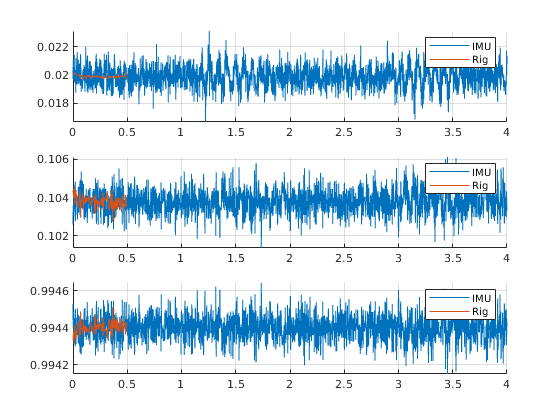

figure(); 
for i = 1:3
    subplot(3,1,i); hold on 
    
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot_2(i,mask_stationary_IMU), "DisplayName","IMU")
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    grid on 
    legend
end

Check that gyro gives reasonable reasults as well

phase_roll_1 = data_IMU.start_and_stop(1,2):data_IMU.start_and_stop(2,1);

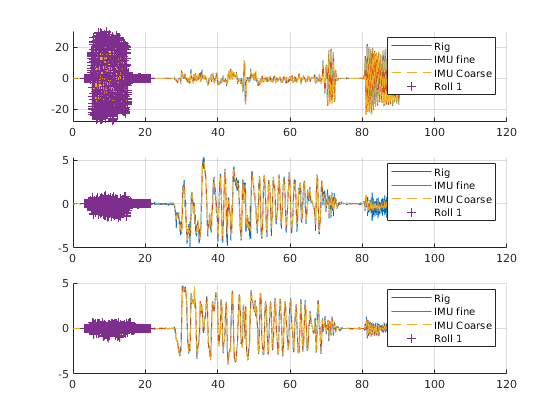

gyro_2 = R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_gyro;
figure()
ax = zeros(3,1);

for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU.time, gyro_2(i,:) , "DisplayName","IMU fine ")
    plot(data_IMU.time, data_IMU_mc_frame.mean_gyro(i,:) ,"--", "DisplayName","IMU Coarse")
    plot(data_IMU.time(phase_roll_1), data_IMU_mc_frame.mean_gyro(i,phase_roll_1) ,"+", "DisplayName","Roll 1", "MarkerIndices",1:10:length(phase_roll_1))
    grid on 
    legend
end

The fine rotation does not matter.

#### Rotatate measurements fine alignment

## Grid search time sync

Extract the phase time sync sequence

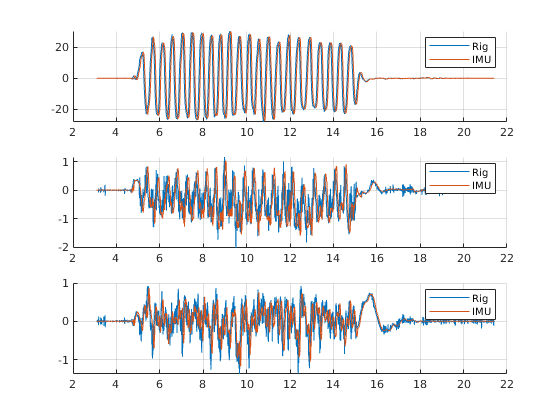


figure
ax = zeros(3,1);
time_IMU = data_IMU.time(phase_roll_1);
mask_time_rig = logical( (t >= time_IMU(1)) .* (t <= time_IMU(end)));
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t(mask_time_rig), w_nb_hat(i,mask_time_rig), "DisplayName","Rig")
    plot(time_IMU, data_IMU_mc_frame.mean_gyro(i,phase_roll_1), "DisplayName","IMU")
    grid on 
    legend
end
slice_time_sync_1_phase = phase_roll_1
% linkaxes(ax);

Interpolate rig w to IMU angular velocity. Use the x direction.

y_interp = data_IMU_mc_frame.mean_gyro(1,slice_time_sync_1_phase);

slice_time_sync_1_phase =         1549        1550        1551        1552        1553        1554        1555        1556        1557        1558        1559        1560        1561        1562        1563        1564        1565        1566        1567        1568        1569        1570        1571        1572        1573        1574        1575        1576        1577        1578        1579        1580        1581        1582        1583        1584        1585        1586        1587        1588        1589        1590        1591        1592        1593        1594        1595        1596        1597        1598


t_interp = time_IMU;
length(t_interp)

% cubic spline iterpolation 
f = @(t_shift) interp1( t, w_nb_hat(1,:),  t_interp - t_shift, 'pchip');
f(0)

cost = @(t_shift) sum((y_interp - f(t_shift)).^2);

ans = 9159

cost(0)

Ocular inspection of coarse time shift 

t_shift_coarse = 0


ans =     0.0545    0.0240   -0.0010    0.0155    0.0494    0.0567    0.0338    0.0000   -0.0477   -0.1029   -0.1122   -0.0681   -0.0165    0.0203    0.0512    0.0565    0.0396    0.0191    0.0029   -0.0114   -0.0133   -0.0013    0.0085    0.0028   -0.0107   -0.0202   -0.0274   -0.0313   -0.0093    0.0351    0.0458    0.0291    0.0075   -0.0129   -0.0325   -0.0345   -0.0108    0.0122    0.0200    0.0249    0.0246    0.0128    0.0032    0.0070    0.0150    0.0171    0.0159    0.0150    0.0219    0.0358


grid_search = t_shift_coarse + (-0.3:0.01:0.3);
cost_grid = arrayfun(cost, grid_search);


ans = 9.3973e+05

options = optimset('Display','iter','TolX', 1e-12);
t_shift_opt = fminbnd(cost,grid_search(1),grid_search(end),options);


t_shift_coarse = 0

data_IMU.time_shifted = data_IMU.time - t_shift_opt;
figure(); clf;
plot(grid_search, cost_grid, "-x")
hold on 
yLim = ylim;
plot(t_shift_opt*ones(1,2), yLim, "-r")

 
 Func-count     x          f(x)         Procedure
    1     -0.0708204  3.98406e+06        initial
    2      0.0708204       154314        golden
    3       0.158359  3.31363e+06        golden
    4      0.0490794      1765.01        parabolic
    5      0.0467631      7436.42        parabolic
    6      0.0510329      301.585        parabolic
    7      0.0509972      301.045        parabolic
    8      0.0509961      301.044        parabolic
    9      0.0509961      301.044        parabolic
   10      0.0509961      301.044        parabolic
   11      0.0509961      301.044        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



ylim(yLim);

### Ensure time shift is ok

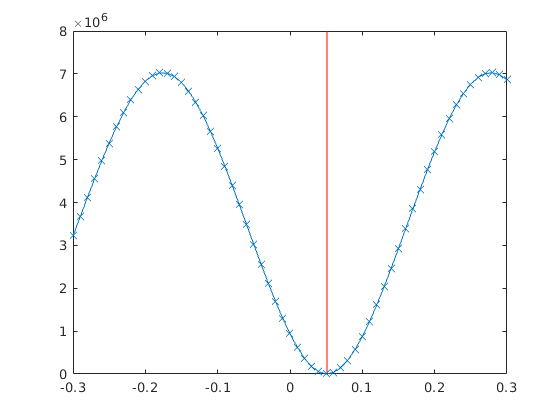

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;
    plot(t, rad2deg(w_nb_hat(i,:))', 'DisplayName', "MC")


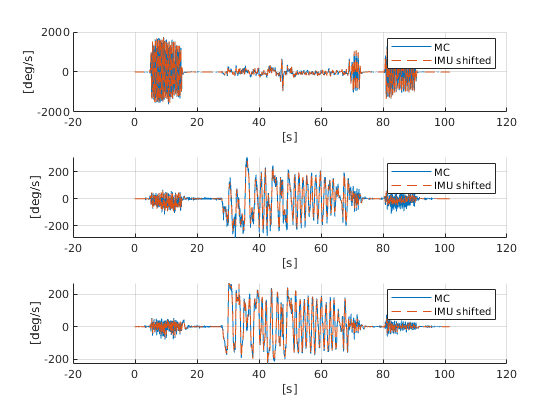

    % plot(data_IMU.time, rad2deg(data_IMU_gyro.gyro_wls_wo_bias_rig_frame_fine(i,:)),'DisplayName','IMU')
    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"--",'DisplayName','IMU shifted')
    
    % yLim = ylim; 
    % X = [data_IMU.start_and_stop(1,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(1,1)];
    % Y = [yLim(2) yLim(2) yLim(1) yLim(1)];
    % fill(data_IMU.time_stamp_corr(X), Y, "b", "FaceAlpha", 0.2);
    % ylim(yLim);
    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
end

figure(); hold on 
plot(data_IMU.time_shifted, "DisplayName","Shifted time")
plot(data_IMU.time, "DisplayName","Original Time")
plot(t, "DisplayName","Rig Time")
legend
grid on 


xlim([0 391])
ylim([-1.35 0.71])

## Find release times

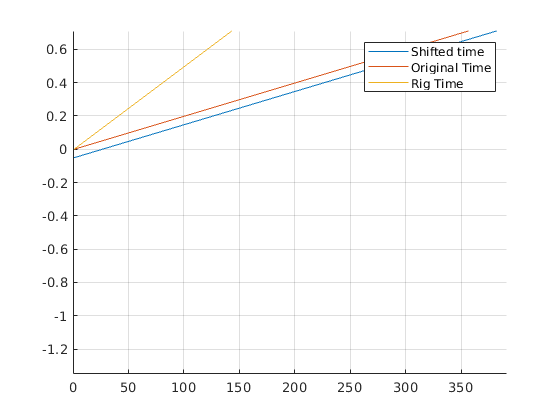



release_times_roll_2 = 80.5 + (0:19)*0.3
release_times_roll_2_end = release_times_roll_2 + 5;

w_roll_2_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2)';
w_roll_2_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2_end)';



release_times_middle = 28 + (0:19)*2.1
release_times_middle_end = release_times_middle + 5;

w_middle_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle)';

release_times_roll_2 =    80.5000   80.8000   81.1000   81.4000   81.7000   82.0000   82.3000   82.6000   82.9000   83.2000   83.5000   83.8000   84.1000   84.4000   84.7000   85.0000   85.3000   85.6000   85.9000   86.2000


w_middle_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle_end)';

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;

release_times_middle =    28.0000   30.1000   32.2000   34.3000   36.4000   38.5000   40.6000   42.7000   44.8000   46.9000   49.0000   51.1000   53.2000   55.3000   57.4000   59.5000   61.6000   63.7000   65.8000   67.9000


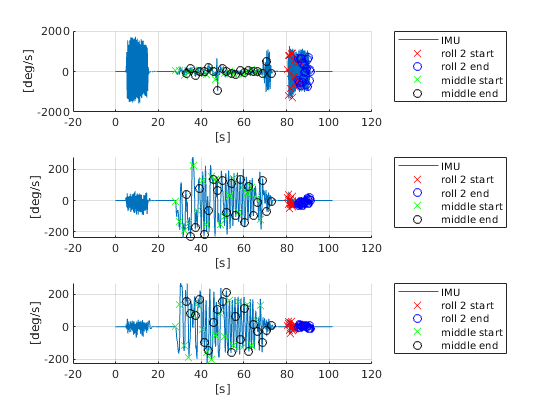


    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"-",'DisplayName','IMU')
    plot(release_times_roll_2, rad2deg(w_roll_2_start(i,:)),"rx",'DisplayName','roll 2 start')
    plot(release_times_roll_2_end, rad2deg(w_roll_2_end(i,:)),"bo",'DisplayName','roll 2 end')
    
    plot(release_times_middle, rad2deg(w_middle_start(i,:)),"gx",'DisplayName','middle start')
    plot(release_times_middle_end, rad2deg(w_middle_end(i,:)),"ko",'DisplayName','middle end')

    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
    legend("Location","bestoutside")
end

## Save Joint data

mkdir(fullfile(pathScript,"estimated_parameters"))

% save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt");
save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt", "release_times_middle", "release_times_roll_2");
% save(fullfile(pathScript,"data_processed","data_initial_values.mat"),"-struct", "data_initial_values");

## Conclusions 

- Coarse alignment is only off by 3 degrees.

- The time-sync was performed on the fine aligned gyroscope wls data, but it is expected that this does not matter if the time-shift estimation was done on the coarse aligned data.

- The time-shift was estimation was done using linearly interpolated data and grid-search. 